clearvars;  
%measurement settings
format shortG
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 14800*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

% Parameters
y_values = -2:1:3; % Increment y from -2 to 2
x_values = -2:1:3; % Increment x from -2 to 2
z_values = 0;  % z values for 0 and 2

% Initialize the matrix to store coordinates
location = zeros(length(y_values) * length(x_values) * length(z_values), 3);

% Loop to generate coordinates
index = 1;
for y = y_values
    for x = x_values
        location(index, :) = [x, y, 0];
        index = index + 1;
    end
end


location = location(:, [2, 1, 3]).*1;

% Specify the common part of the file name
file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX02072024_D32N52_test3\sensor_';
file_suffix = '_averages.csv';

% Loop to create variables sen1, sen2, ..., sen16
for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];

    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');

        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));

        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];

        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

% Number of sensors
num_sensors = 16;

sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

% Adjust the location for the magnet
loc = location + [0, 0, 22];

01312024

calculate magnetic field strengths of other magnets - find combination with largets magnetic field strength 

Redo measurements closer to sensor (maybe try n52 right away)

Use smallest magnet "reasonably" detecable at 2 cm. (just measure all of them at 2cm)

    Use strongest magnet, play with z-distance, decreae

Try fitting with center 4 sensors only

% Create a cell array to store all rows
all_sen = cell(length(data_matrix), 16);

% Access each row of each matrix and store in the cell array
for row = 1:length(data_matrix)
    for sensor = 1:16
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

all_sen

all_sen = 36×16 cell array
    {[-0.42516 0.17405 0.56384]}    {[ -0.31222 0.2322 0.84831]}    {[-0.074325 0.27482 0.99092]}    {[0.22563 0.25873 0.92865]}    {[-0.45565 -0.012315 0.61809]}    {[ -0.3438 -0.037035 0.91111]}    {[-0.074445 -0.02964 1.1362]}    {[ 0.24783 -0.044565 1.0297]}    {[ -0.42445 -0.21267 0.55769]}    {[  -0.30991 -0.28745 0.8235]}    {[-0.067545 -0.33673 0.97415]}    {[  0.2151 -0.31077 0.88785]}    {[-0.32095 -0.30408 0.38964]}    {[ -0.23934 -0.4048 0.57942]}    {[-0.05013 -0.45804 0.67547]}    {[0.15646 -0.44145 0.62678]}
    {[-0.40899 0.20958 0.53586]}    {[-0.29689 0.27685 0.80634]}    {[-0.071655 0.32577 0.93932]}    {[0.21759 0.30927 0.88023]}    {[  -0.45606 0.03117 0.61877]}    {[  -0.34037 0.02613 0.91321]}    {[-0.073305 0.047085 1.1372]}    {[   0.24894 0.02838 1.0307]}    {[ -0.44124 -0.17388 0.58876]}    {[ -0.32295 -0.23734 0.86624]}    {[ -0.068595 -0.28021 1.0256]}    {[ 0.22599 -0.25987 0.93572]}    {[-0.34169 -0.29291 0.42766]}    {[ -0.2553

multipreds = [];
multifvals = [];
for t = 1:length(sen1)
        tt = [all_sen{t,:}];
        costfun = @(v)mmcost(v, B_t, sensor_actual, tt, 1, 16);
        nonlcon = @con;

        x0 = [0, 0, 0, 5, 5, 55];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-1, -1, -1, -100, -100, 0];
        ub = [1, 1, 1, 100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        multipreds = [multipreds; locs];
        multifvals = [multifvals; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

multiang = multipreds(:,1:3)

multiang =     -0.044971     0.023382      0.91943
    -0.050665      0.03427      0.92158
    -0.063897     0.044389      0.91737
    -0.060541     0.051435      0.91304
    -0.061712     0.064153       0.9032
    -0.055281     0.062898      0.89607
     -0.03748  -0.00032485       0.9257
    -0.043853     0.016987      0.92501
    -0.045886     0.030278      0.92139
    -0.049654     0.042806      0.91456


multiloc = multipreds(:,4:6)

multiloc =       -3.6241      -2.4833       22.269
      -3.6481      -1.3843       22.279
      -3.7214     -0.28932       22.242
       -3.686      0.77885       22.206
      -3.6804       1.9438       22.079
      -3.4921       2.8165       22.121
      -2.4593      -2.7658       22.406
      -2.4904      -1.5962       22.406
      -2.4777     -0.47093        22.38
      -2.4985      0.63142       22.322


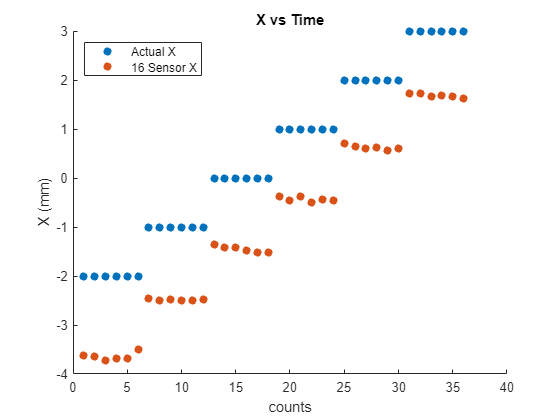

scatter(1:length(multiloc),loc(:,1), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-3,4])
legend('Actual X','16 Sensor X', Location='northwest')
hold off;

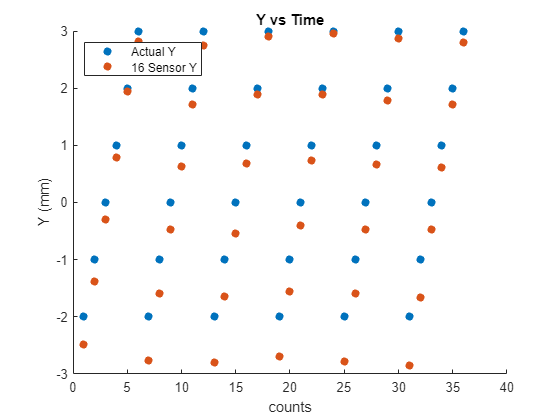

scatter(1:length(multiloc),loc(:,2), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%lim([-3,7])
legend('Actual Y','16 Sensor Y', Location='northwest')
hold off;

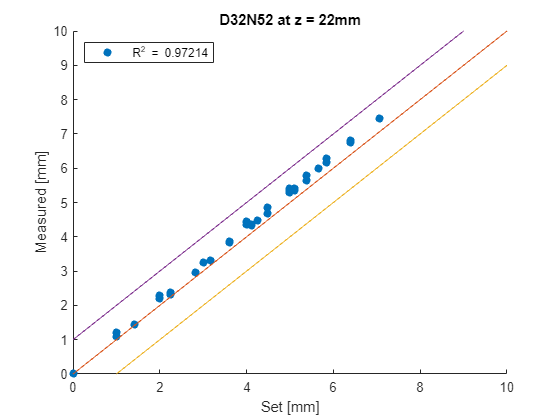

r0 = [multiloc(1,1) multiloc(1,2) multiloc(1,3)];
testx =sqrt(sum((multiloc-r0).^2, 2));
zi = [5.000
5.099
5.385
5.831
6.403
7.071
5.099
5.196
5.477
5.916
6.481
7.141
5.385
5.477
5.745
6.164
6.708
7.348
5.831
5.916
6.164
6.557
7.071
7.681
6.403
6.481
6.708
7.071
7.550
8.124
7.071
7.141
7.348
7.681
8.124
8.660
];

r02 = [location(1,1) location(1,2) location(1,3)];
zi2 = sqrt(sum((location-r02).^2, 2));

scatter(zi2, testx, 'filled')
hold on;
plot(0:10, 0:10)
plot(0:10, -1:9)
plot(0:10, 1:11)
ylim([0 10])
xlabel("Set [mm]")
ylabel('Measured [mm]')
title('D32N52 at z = 22mm')
legend('R^2 = 0.97214', Location = 'northwest')
hold off;

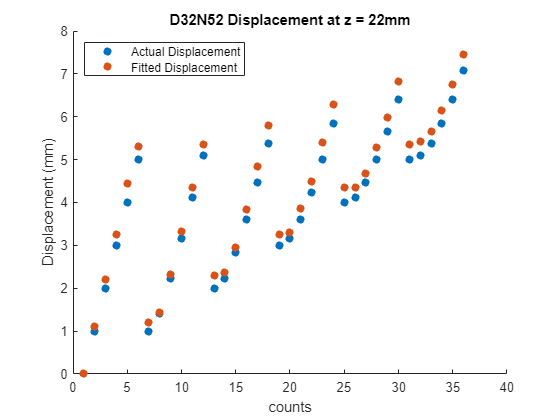


scatter(1:length(zi2), zi2, 'filled')
hold on;
scatter(1:length(testx), testx, 'filled')
title('D32N52 Displacement at z = 22mm')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

SSR = sum((zi2 - testx).^2)

SSR =        2.8836


SST = sum((zi2 - mean(testx)).^2)

SST =        103.52


R2 = 1 - SSR/SST

R2 =       0.97214


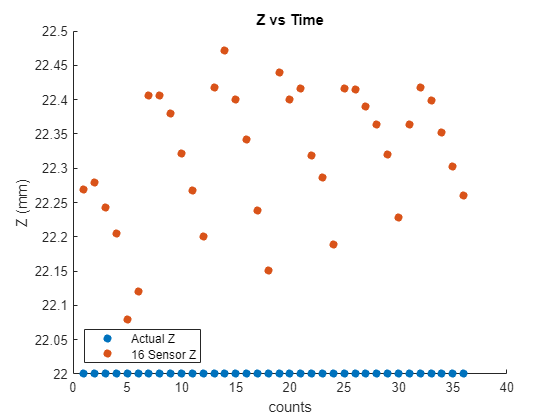

scatter(1:length(multiloc),loc(:,3), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([31,33])
legend('Actual Z','16 Sensor Z', Location='southwest')
hold off;

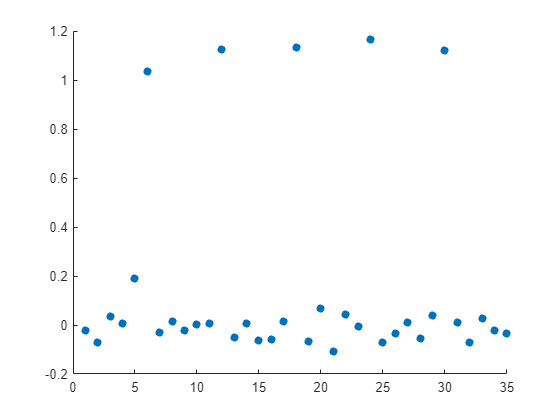

test = diff(multiloc(:,1));
scatter(1:length(test), test, 'filled')
hold on;
hold off;

multidisp = multiloc + [2 2 -22]

multidisp =       -1.6241     -0.48326      0.26918
      -1.6481      0.61571       0.2791
      -1.7214       1.7107        0.242
       -1.686       2.7788      0.20552
      -1.6804       3.9438     0.078965
      -1.4921       4.8165      0.12072
     -0.45925     -0.76579      0.40556
     -0.49035      0.40375      0.40587
     -0.47772       1.5291       0.3796
     -0.49852       2.6314      0.32208


multidisp = sqrt(sum(multidisp.^2, 2))

multidisp =        1.7157
       1.7814
       2.4389
       3.2568
       4.2876
       5.0437
      0.98073
      0.75379
       1.6463
       2.6975



disp = [4.98 5.08 5.35 5.78 6.34 7.01 5.08 5.18 5.45 5.9 6.46 7.12 5.37 5.47 5.74 6.13 6.66 7.3 5.81 5.91 6.15 6.55 7.05 7.67 6.41 6.47 6.70 7.05 7.55 8.11 7.06 7.13 7.34 7.67 8.1 8.65]'

disp =          4.98
         5.08
         5.35
         5.78
         6.34
         7.01
         5.08
         5.18
         5.45
          5.9


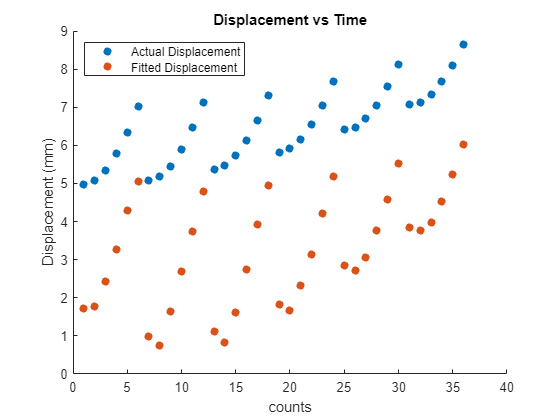


scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('Displacement vs Time')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

function a = anglecost(v, loc, B_data, B_t, datasize, sensor)
X1 = sensor - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t, sensor)
X1 = sensor - [x(1) x(2) x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function s = senloc(x, loc, B_data, B_t, datasize)
X1 = [x(1) x(2) x(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 -1], datasize, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function m = multicost(v, sen1, sen2, sen3, sen4, B_t)
loc = [v(4) v(5) v(6)];
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X2 = [-25 0 0] - loc;
R2 = sqrt(sum(X2.^2, 2));
X3 = [0 25 0] - loc;
R3 = sqrt(sum(X3.^2, 2));
X4 = [-25 25 0] - loc;
R4 = sqrt(sum(X4.^2, 2));
m = sum(sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2) + sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2) ...
    + sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2) + sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2));
end

function mm = mmcost(v, B_t, sensor_grid, sensor_data, s1, s2)
    H_0 = repelem([v(1) v(2) v(3)], 1, 1);
    loc = [v(4) v(5) v(6)];
    s = sensor_data;
    mm = 0;
    for i = s1:s2
        X = sensor_grid(i, :) - loc;
        R = sqrt(sum(X.^2, 2));
        mm = mm + sum((s(3*i-2:3*i) - B_t * (3 * dot(H_0, X, 2) .* X ./ R.^5 - H_0 ./ R.^3)).^2);
    end
end